%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CODE CHALLENGE 2 - Monte Carlo Analysis
%
% The purpose of this challenge is to perform a Monte-Carlo analysis on the
% lift generated by an aircraft.  The aircraft has the following characteristics:
%   Wing surface area, S = 80 m^2
%   Lift coefficient, C_L = 0.90 +- 0.03
%
% And is flying under the following conditions
%   Air density, rho = 0.653 kg/m^3
%   Airspeed, V = 100 +- 10 m/s
%
% ---------------------------------------------------------------------------------
%
% To complete the challenge, execute the following steps:
% 1) Sample S, C_L, rho, and V 10,000 times.
% 2) Calculate lift in kilonewtons for each of the 10,000 samplings/simulations.
% 3) Calculate the best estimate and error for lift and report it to the
% command window using appropriate significant figures.
% 4) Plot a histogram of L.
% Bonus 1) Calculate drag in kilonewtons for each of the 10,000
% samplings/simulations.
% Bonus 2) Make a scatterplot of Lift vs Drag.
%
% NOTE: DO NOT change any variable names already present in the code.
% 
% Upload your team's script to Canvas to complete the challenge.
% 
% NAME YOUR FILE AS Challenge2_Sec{section number}_Group{group breakout #}.m 
% ***Section numbers are 1 or 2*** 
% EX File Name: Challenge2_Sec1_Group15.m 
%
%
% 1) Tristan Workman
% 2) Alicia Wu
% 3) Brandi Scarboro
% 4) Jade Babcock-Chi
% 5) Bradley Bishop
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Housekeeping

(Please don't "clear all" or "clearvars", it makes grading difficult)

close all   % Close all open figure windows
clc         % Clear the command window

## 1) Sample S, C_L, rho, and V 10,000 times

(i.e. the S variable should contain 10000 samples of the wing surface area)

N = 1e04;
% list all the values and their uncertainties
C_Lorig = 0.9;
C_Luncer = 0.03;
rhoOrig = 0.653;
Vorig = 100;
Vuncer = 10;
% samples!
S = 80 * ones(N,1);
C_L = C_Luncer * randn(N,1) + C_Lorig;
rho = 0.653 * ones(N,1);
V = Vuncer * randn(N,1) + Vorig;

## 2) Calculate lift in kilonewtons for each of the 10,000 samplings/simulations.

Given that the equation for lift is: L = 0.5 * rho * V^2 * C_L * S (Newtons)

% lift equation!
L = (0.5 .* rho .* V.^2 .* C_L .* S) ./ 1000;

## 3) Calculate the best estimate and error for lift

Report it to the command window using appropriate significant figures.

% find the error! :^)
L_best = mean(L)

L_best = 237.4977

L_err = (mean(sqrt(((0.5 .* rho .* 2 .* V .* C_L .* S) .* Vuncer).^2 + ((0.5 .* rho .* V.^2 .* S) * C_Luncer).^2)) ./ 1000)

L_err = 47.6896

% test to see if its reasonable!!!
a = L_best + L_err;
b = L_best - L_err;

## 4) Plot a histogram (use the "histogram" command) of L with 30 bins.

Add annotations and labels for style points!

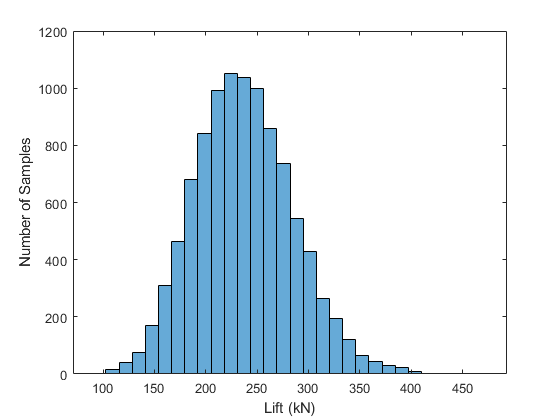

% nice histogram!
histogram(L,30)
xlabel("Lift (kN)")
ylabel("Number of Samples")

## Bonus 1) Calculate drag in kilonewtons

For each of the 10,000 samplings/simulations, given that the equation for drag is: D = 0.5 * rho * V^2 * C_D * S (Newtons) and that C_D = 0.070 +- 0.005

% establish best estimate and uncertainty variables
C_Dorig = 0.07;
C_Duncer = 0.005;
% create 10000 samples using established numbers
C_D = C_Duncer * randn(N,1) + C_Dorig;
% calculate drag using values from C_D
D_all = (0.5 .* rho .* V.^2 .* C_D .* S) ./ 1000;
D = mean((0.5 .* rho .* V.^2 .* C_D .* S) ./ 1000)

D = 18.4785

% using the general method, propogate error through the drag equation to
% determine uncertainty
D_err = (mean(sqrt(((0.5 .* rho .* 2 .* V .* C_D .* S) .* Vuncer).^2 + ((0.5 .* rho .* V.^2 .* S) .* C_Duncer).^2)) ./ 1000)

D_err = 3.8923

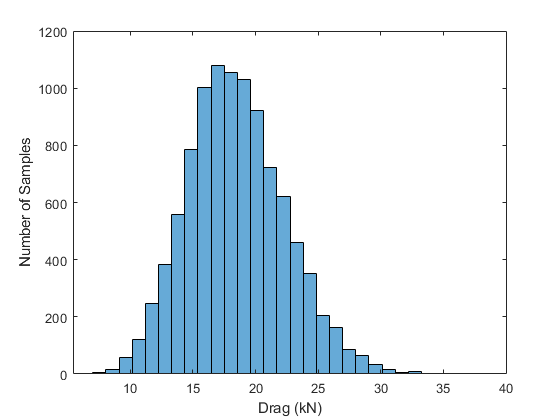

% graph values of drag to confirm normal distribution
histogram(D_all,30)
xlabel("Drag (kN)")
ylabel("Number of Samples")

## Bonus 2) Make a scatterplot of Lift vs Drag.

Think about the following (no work to do): - Why do you think the points are spread into an ellipse and not a circle? - What is the significance of the general trend/slope of the data? - How could this sort of analysis be useful when dealing with more complicated systems and equations?

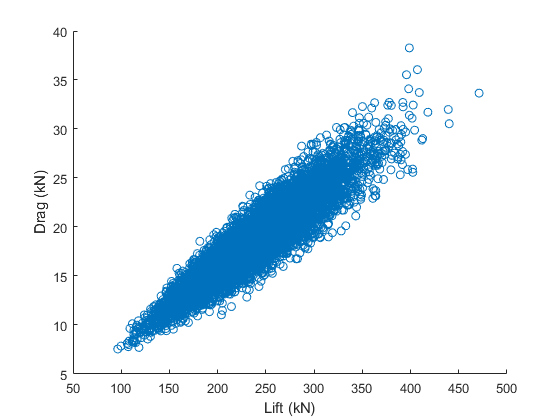

scatter(L,D_all)
xlabel("Lift (kN)")
ylabel("Drag (kN)")

% it appears there is a general trend of proportionality between drag and
% lift, where an increase in one stipulates an increase in the other.